# 磁链及增量电感LUT计算程序

clear
load('./temp/faifDataRaw.mat')

% 打开APP，部分操作在GUI界面完成
curveFitter

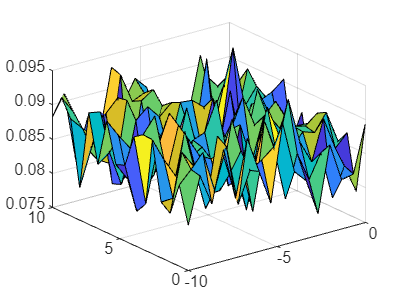

Rs=(UdR2 - UdR1)/(IdR2-IdR1);
surf(IdX,IqY,Rs)

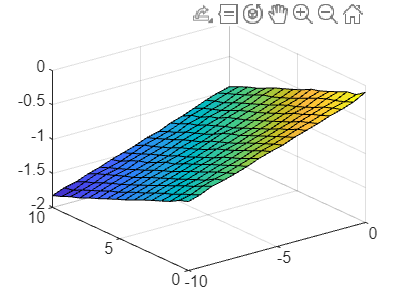

surf(IdX,IqY,Ud1)

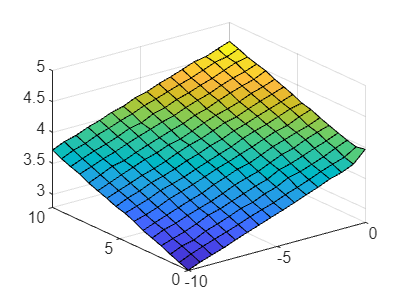

surf(IdX,IqY,Uq1)

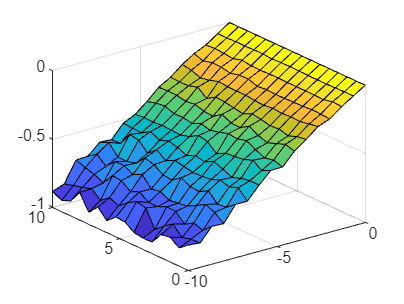


surf(IdX,IqY,IdX.*Rs)

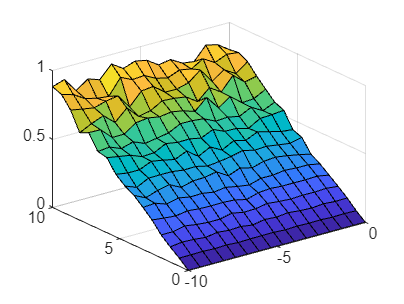

surf(IdX,IqY,IqY.*Rs)

% 由于测试顺序是十分规律的，可以尝试拟合下Rs以减小误差
% 这里温度是又升又降的，可考虑滤波

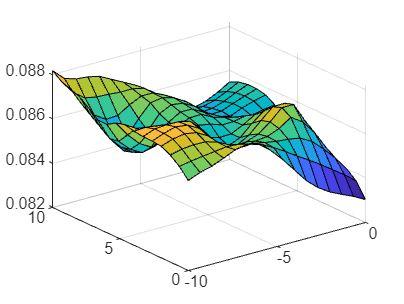

% 查看拟合效果
Rs2=fittedmodel(IdX,IqY);
surf(IdX,IqY,Rs2)

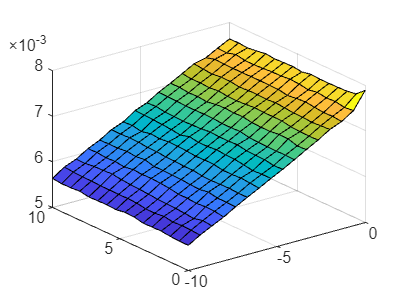

faiq=-(Ud1-IdX.*Rs2)/omegaE;
faid=(Uq1-IqY.*Rs2)/omegaE;
surf(IdX,IqY,faid)

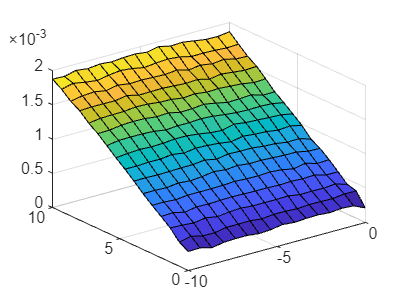

surf(IdX,IqY,faiq)

% 同样的把faid faiq 拟合了

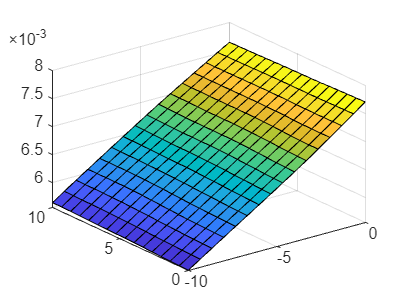

% 查看拟合效果
faid2=fittedmodel1(IdX,IqY);
surf(IdX,IqY,faid2)

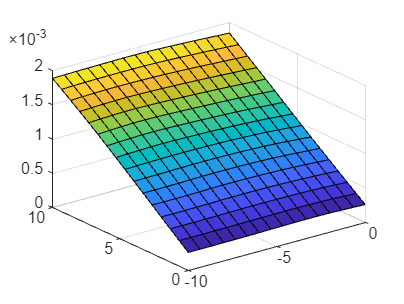

faiq2=fittedmodel2(IdX,IqY);
surf(IdX,IqY,faiq2)

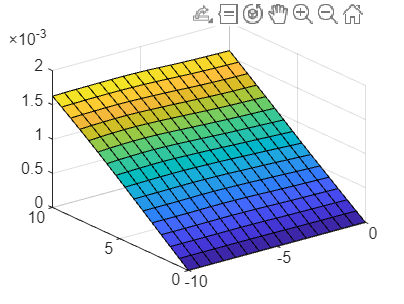

% 把faiq强行做成"关于Iq奇对称"的
[faiq2m, faiq2n] = size(faiq2);
faiq3=faiq2-repmat(faiq2(1,:), faiq2m, 1);
surf(IdX,IqY,faiq3)

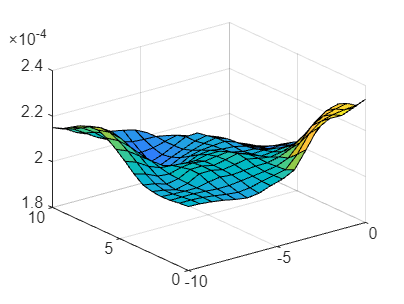

% 用内建梯度算法求取
[Ldd_inc,Lqd_inc]=gradient(faid2,-step,step);
surf(IdX,IqY,Ldd_inc)

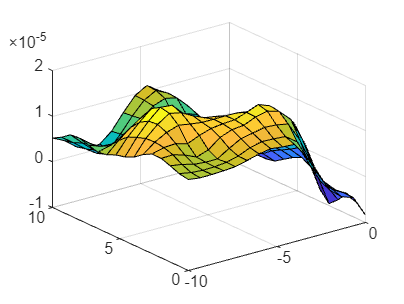

surf(IdX,IqY,Lqd_inc)

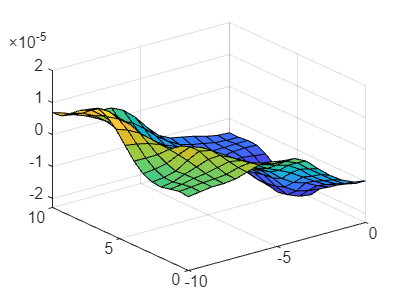

[Ldq_inc,Lqq_inc]=gradient(faiq2,-step,step);
surf(IdX,IqY,Ldq_inc)

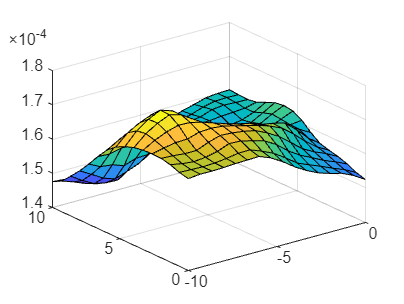

surf(IdX,IqY,Lqq_inc)

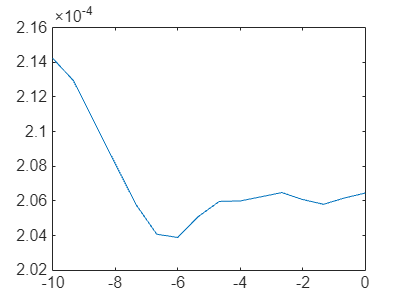

% 获得PI控制器所需电感
% 认为Ld主要与Id有关，对Iq因素取平均
Ld_inc=mean(Ldd_inc);
% 认为Lq主要与Iq有关，对Id因素取平均
Lq_inc=mean(Lqq_inc, 2);

plot(IdX(1,:),Ld_inc)

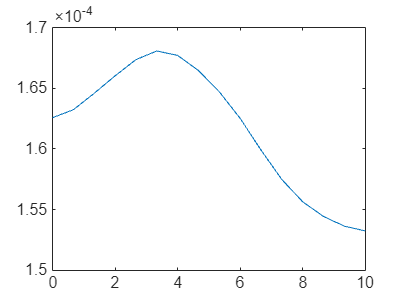

plot(IqY(:,1),Lq_inc)

% 生成C语言数组字符串，并复制到剪贴板
% 这里恰好会"转置"输出，从而符合C的顺序
result = exportMatrixToC(faid2,'psidLUTpu16negIdxIqy');
result = [result exportMatrixToC(faiq3,'psiqLUTpu16negIdxIqy')];
result = [result exportMatrixToC(Ld_inc,'LdLUTpu16negId')];
result = [result exportMatrixToC(Lq_inc,'LqLUTpu16Iq')];

result

result =     'const float psidLUTpu16negIdxIqy[256] = {7.702147e-03, 7.696554e-03, 7.693423e-03, 7.689146e-03, 7.682973e-03, 7.676324e-03, 7.673097e-03, 7.671786e-03, 7.670063e-03, 7.667541e-03, 7.664109e-03, 7.659824e-03, 7.655852e-03, 7.652751e-03, 7.650618e-03, 7.648142e-03, 7.546292e-03, 7.543691e-03, 7.541171e-03, 7.538279e-03, 7.535715e-03, 7.534656e-03, 7.536120e-03, 7.536726e-03, 7.536485e-03, 7.535635e-03, 7.533951e-03, 7.531027e-03, 7.528199e-03, 7.525803e-03, 7.524548e-03, 7.523896e-03, 7.393482e-03, 7.391462e-03, 7.390301e-03, 7.389506e-03, 7.391194e-03, 7.395737e-03, 7.399774e-03, 7.401938e-03, 7.402841e-03, 7.403080e-03, 7.402450e-03, 7.401025e-03, 7.399416e-03, 7.398364e-03, 7.397819e-03, 7.397756e-03, 7.240231e-03, 7.239639e-03, 7.240308e-03, 7.243732e-03, 7.250149e-03, 7.257419e-03, 7.263359e-03, 7.267131e-03, 7.269372e-03, 7.270222e-03, 7.269894e-03, 7.269615e-03, 7.269588e-03, 7.269919e-03, 7.270187e-03, 7.270944e-03, 7.087241e-03, 7.089406e-03, 7.093376e-03, 7.10132


clipboard('copy', result);

function result = exportMatrixToC(MAT2export,varName)

    result = sprintf('const float %s[%d] = {', varName, numel(MAT2export));

    for i = 1:numel(MAT2export)
            result = [result, sprintf('%d, ', MAT2export(i))];
    end
    
    result = [result, sprintf('}; \n')];
end